# **Analysis of ORSO RoundRobin Samples**

**This is ana anlysis of the INTER roundRobin sample data carried out using **the RAT toolbox. We start by doing a Bayesian analysis of "Sample 1" as a 1 layer model. Then, we use Nested Sampling to examine the 'how many layers' problem.

## Sample 1

Start by loading in the data, and plotting it to see what we have...

fileDir = fileparts(which('roundRobin'));
sample1 = readtable([fileDir filesep 'INTER' filesep 'IvsQ_49162_49163_49164_49165.txt']);
sample1 = table2array(sample1);

figure(1); clf
errorbar(sample1(:,1),sample1(:,2),sample1(:,3),'b.')
set(gca,'YScale','log','XScale','log')

Now we need to create a RAT project. It's an air substrate sample (air against SIlicon).

problem = createProject(name = "RoundRobin Sample1", geometry = "air/substrate");

% Change the substrate from D2O (default) to Silicon
problem.setBulkOut(1,'name','Silicon','min',2.073e-6,'max',2.073e-6,'value',2.073e-6,'fit',false);
% Modify the default value for the scalefactor
problem.setScalefactor(1,'min',0.8,'value',1.0,'max',1.2);


It's clear the sample has at least one layer (we will examine this later). Add the necessary parameters and a layer to the project..

params = {{"Layer 1 Thick", 50,     1000,   3000,    true};
          {"Layer 1 SLD",   1e-6,   3e-6,   13e-6,   true};
          {"Layer 1 Rough", 1,      4,      20,     true}};

problem.addParameterGroup(params);

% Group these into a layer
problem.addLayer('Layer 1','Layer 1 Thick','Layer 1 SLD','Layer 1 Rough');

Also add the data to out project....

problem.addData('Inter 1',sample1);

Now we have all we need to make a contrast...


problem.addContrast('name', 'Inter Data 1',...
                    'bulkIn',  'SLD Air',...
                    'bulkOut',  'Silicon',...
                    'resolution','Resolution 1',...
                    'Background','Background 1',...
                    'Scalefactor', 'Scalefactor 1',...
                    'Data', 'Inter 1');
problem.setContrastModel(1,'Layer 1');

Finally, we make a few experimental parameters fittable....

problem.setResolutionParam(1,'fit',true);
problem.setScalefactor(1,'fit',true);
problem.setBackgroundParam(1,'fit',true,'min',-1e-7);
problem.setParameter('Substrate Roughness','min',1,'max',20)

ans =          modelType: 'standard layers'
    experimentName: "RoundRobin Sample1"
          geometry: 'air/substrate'


    Parameters: ---------------------------------------------------------------------------------------------- 

    p            Name              Min     Value      Max      Fit? 
    _    _____________________    _____    _____    _______    _____

    1    "Substrate Roughness"        1        3         20    true 
    2    "Layer 1 Thick"             50     1000       3000    true 
    3    "Layer 1 SLD"            1e-06    3e-06    1.3e-05    true 
    4    "Layer 1 Rough"              1        4         20    true 


    Bulk In: -------------------------------------------------------------------------------------------------- 

    p      <

Take a look at what we have. We make a controls block (which will be set to 'calculate' by default), and send this to RAT..

% Make a controls classs...
controls = controlsClass();


% ..send to RAT....
[problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________

Elapsed time is 0.002157 seconds.

Finished RAT ______________________________________________________________________________________________ 



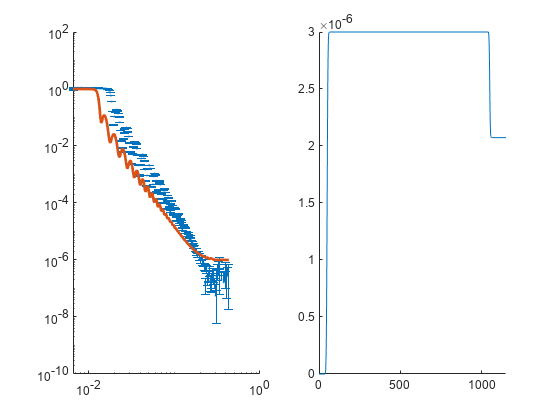


% ..plot the results
plotRefSLD(problem,results);

Run some differential evoution to get a starting fit....

controls.procedure = 'DE';
controls.display = 'final';
[problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________


Running Differential Evolution

Final chi squared is 2.33882
Elapsed time is 1.074811 seconds.

Finished RAT ______________________________________________________________________________________________ 



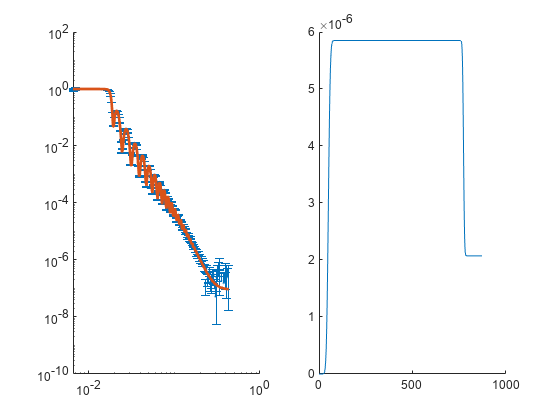

clf; plotRefSLD(problem,results)

## Bayesian Analysis

Now that we have a resonable strating fit, run a Bayesian analysis to see what we have. We do this using DREAM

controls.procedure = 'dream';

controls.display = 'final';

Use the defaults and just run it....

[problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________


Running DREAM

------------------ Summary of the main settings used ------------------


DREAMPar = struct with fields:
             d: 7
             N: 10
             T: 5000
      parallel: 0
           CPU: 1
        lambda: 0.500000000000000
    pUnitGamma: 0.200000000000000
           nCR: 3
         delta: 3
         steps: 100
          zeta: 1.000000000000000e-12
       outlier: 'iqr'
      adaptPCR: 0
      thinning: 1
       epsilon: 0.025000000000000
           ABC: 0
            IO: 0
        modout: 0
       restart: 0
          save: 0
             R: [10×10 double]


-----------------------------------------------------------------------

 DREAM:    0.0% [........................................]


 DREAM:  100.0% [****************************************]
Elapsed time is 8.456668 seconds.

Finished RAT ______________________________________________________________________________________________ 



Plot some of the Bayes results....

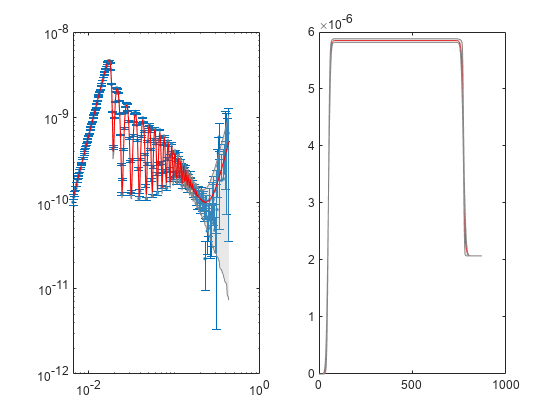

figure(30); clf;
bayesShadedPlot(problem,results,'fit','average','KeepAxes',true,'interval',65,'q4',true);

    h4 = figure(5); clf

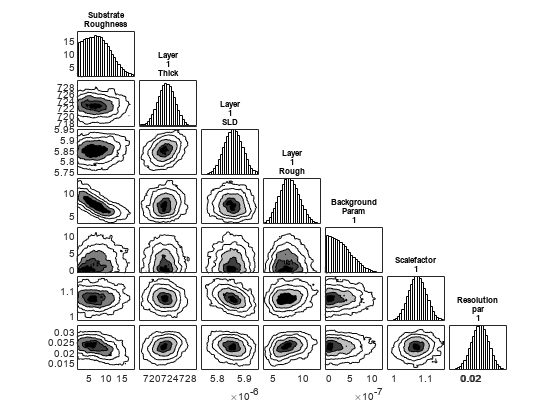

    cornerPlot(results,h4,'smooth',false)

Save these reults for later...

    resultsInter = results;

## The 'how many layers?' question.....

Standard Bayesian analysis does not output the evidence term (the denominator in Bayes rule). This is requred in order to distinguish between models using Bayesian model selection. Bayesian evidence is calculable using Nested Sampling however, so we can use the in-built sampler in RAT to tackle this question. In this case, it's clear that the 'main' sample is our single layer as described above. For samples on Silicon, the oxide layer is occasianally visible, so let's make a 2 layer model including oxide, and use Nested Sampling to see if the oxide is necessary.

Make a version of our project with an extra layer....

    % Save our one layer project for later...
    save('problem1L','problem');

    % Whilst it is one layer, run the nested sampler with this...
    controls.procedure = 'ns';
    controls.display = 'final';
    [problem1L,results1L] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________


Running Nested Sampler

log(Z): -1.88877e+05, tol = 1.88533e+05, K = 1, iteration = 1, H = NaN
log(Z): -1.69929e+05, tol = 1.69585e+05, K = 1, iteration = 2, H = 5.02063e+00
log(Z): -1.67919e+05, tol = 1.67576e+05, K = 1, iteration = 3, H = 5.02730e+00
log(Z): -1.51299e+05, tol = 1.50955e+05, K = 1, iteration = 4, H = 5.03397e+00
log(Z): -1.47031e+05, tol = 1.46687e+05, K = 1, iteration = 5, H = 5.04063e+00
log(Z): -1.36875e+05, tol = 1.36531e+05, K = 1, iteration = 6, H = 5.04730e+00
log(Z): -1.22035e+05, tol = 1.21691e+05, K = 1, iteration = 7, H = 5.05397e+00
log(Z): -1.11211e+05, tol = 1.10867e+05, K = 1, iteration = 8, H = 5.06063e+00
log(Z): -1.02934e+05, tol = 1.02590e+05, K = 1, iteration = 9, H = 5.06730e+00
log(Z): -9.87835e+04, tol = 9.84396e+04, K = 1, iteration = 10, H = 5.07397e+00
log(Z): -8.99173e+04, tol = 8.95734e+04, K = 1, iteration = 11, H = 5.08063e+00
l


    % The evidence term is in results....
    evidence1L = results1L.bayesRes.nestOutput.LogZ;

    % Now for another layer. Add some parameters, and group them into a new layer.....
    params = {{"Oxide Thick", 10,     50,   100,    true};
          {"Oxide SLD",   3e-6,   3.4e-6,  5e-6,   true};
          {"Oxide Rough", 1,      4,      20,     true}};

    problem.addParameterGroup(params);

    % Group these into a layer
    problem.addLayer('Oxide','Oxide Thick','Oxide SLD','Oxide Rough');

    % Make our contrast into a two layer problem....
    problem.setContrastModel(1,{'Oxide','Layer 1'})

ans =          modelType: 'standard layers'
    experimentName: "RoundRobin Sample1"
          geometry: 'air/substrate'


    Parameters: ---------------------------------------------------------------------------------------------- 

    p            Name              Min            Value              Max      Fit? 
    _    _____________________    _____    ____________________    _______    _____

    1    "Substrate Roughness"        1         7.4579748212117         20    true 
    2    "Layer 1 Thick"             50        722.754853631392       3000    true 
    3    "Layer 1 SLD"            1e-06    5.85413047337852e-06    1.3e-05    true 
    4    "Layer 1 Rough"              1        7.14880355473191         20    true 
    5    "Oxide Thick"               10                


    % Run some DE to get an initial solution...
    controls.procedure = 'DE';
    [problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________


Running Differential Evolution

Final chi squared is 2.2363
Elapsed time is 1.260441 seconds.

Finished RAT ______________________________________________________________________________________________ 



Run the Nested Sampler with the 2 layer problem

    controls.procedure = 'ns'

controls =   controlsClass with properties:

            parallel: 'single'
           procedure: 'ns'
    calcSldDuringFit: 0
             display: 'final'
               Nlive: 150
               Nmcmc: 0
           propScale: 0.100000000000000
         nsTolerance: 0.100000000000000
           resamPars: [0.900000000000000 50]


    % Run the 1 Layer problem......
    [problem2L,results2L] = RAT(problem,controls)

Starting RAT ________________________________________________________________________________________________


Running Nested Sampler

log(Z): -1.82700e+05, tol = 1.82413e+05, K = 1, iteration = 1, H = NaN
log(Z): -1.23141e+05, tol = 1.22854e+05, K = 1, iteration = 2, H = 5.02063e+00
log(Z): -1.20861e+05, tol = 1.20574e+05, K = 1, iteration = 3, H = 5.02730e+00
log(Z): -1.07419e+05, tol = 1.07131e+05, K = 1, iteration = 4, H = 5.03397e+00
log(Z): -1.03704e+05, tol = 1.03417e+05, K = 1, iteration = 5, H = 5.04063e+00
log(Z): -9.47839e+04, tol = 9.44968e+04, K = 1, iteration = 6, H = 5.04730e+00
log(Z): -9.39541e+04, tol = 9.36670e+04, K = 1, iteration = 7, H = 5.05397e+00
log(Z): -9.36300e+04, tol = 9.33429e+04, K = 1, iteration = 8, H = 5.06063e+00
log(Z): -9.04185e+04, tol = 9.01314e+04, K = 1, iteration = 9, H = 5.06730e+00
log(Z): -9.00778e+04, tol = 8.97907e+04, K = 1, iteration = 10, H = 5.07397e+00
log(Z): -8.67521e+04, tol = 8.64650e+04, K = 1, iteration = 11, H = 5.08063e+00
l

problem2L =          modelType: 'standard layers'
    experimentName: "RoundRobin Sample1"
          geometry: 'air/substrate'


    Parameters: ---------------------------------------------------------------------------------------------- 

    p            Name              Min            Value              Max      Fit? 
    _    _____________________    _____    ____________________    _______    _____

    1    "Substrate Roughness"        1        5.74510626066891         20    true 
    2    "Layer 1 Thick"             50        713.345337599187       3000    true 
    3    "Layer 1 SLD"            1e-06    5.85000577588524e-06    1.3e-05    true 
    4    "Layer 1 Rough"              1        6.41896117285536         20    true 
    5    "Oxide Thick"               10        13

results2L = struct with fields:
          reflectivity: {[211×2 double]}
            simulation: {[211×2 double]}
           shiftedData: {[211×3 double]}
             layerSlds: {[2×3 double]}
           sldProfiles: {[877×2 double]}
             allLayers: {[0 0 0]}
    calculationResults: [1×1 struct]
        contrastParams: [1×1 struct]
           bestFitPars: [5.745106260668912 7.133453375991875e+02 5.850005775885237e-06 6.418961172855355 13.283417451189855 4.118271586496507e-06 5.133671996861613 2.246118240615957e-07 1.074167534263704 0.023464274612892]
          bestFitsMean: [1×1 struct]
              predlims: [1×1 struct]
           parConfInts: [1×1 struct]
              bestPars: [5.745106260668912 7.133453375991875e+02 5.850005775885237e-06 6.418961172855355 13.283417451189855 4.118271586496507e-06 5.133671996861613 2.246118240615957e-07 1.074167534263704 0.023464274612892]
              bayesRes: [1×1 struct]
                 chain: [718×10 double]
              fitNames:

The evidence term is in results.....

    twoLayerEvidence = results2L.bayesRes.nestOutput.LogZ

twoLayerEvidence =  -24.891641123550322


Now we can compare the two evidence values....

    evDiff = exp(evidence1L - twoLayerEvidence);

    fprintf('Nested sampling suggests that the one layer model is %g times more likely than the two layer \n', evDiff)

Nested sampling suggests that the one layer model is 25.6921 times more likely than the two layer 


    fprintf('..or a one layer model is more likely by a confidence level of %g %% \n', (evDiff / (1+evDiff)) * 100)

..or a one layer model is more likely by a confidence level of 96.2536 % 


Clearly, our 1 layer model result is the most appropriate for this data

## Data from Other Instruments....

We can now check the results from the other instruments. We need to use out 1 layer model, so we can either load out saved one back in, or just remove our extra paramers..

% Either modify current......
%     problem.removeLayer(2);
%     problem.removeParameter('Oxide Thick');
%     problem.removeParameter('Oxide SLD');
%     problem.removeParameter('Oxide Rough');
%     problem.setContrastModel(1,'Layer 1');

% or... load in saved copy...
p = load('problem1L.mat');
problem = p.problem;


Now add the data from CRISP and PolRef

    
    polRefDat = readtable([fileDir filesep 'POLREF' filesep 'Sample_1_Round_Robin_PolRef.dat']);
    polRefDat = table2array(polRefDat);

    problem.addData('Polref',polRefDat);

Set our contrast to look at the new data, and do some fitting....

    problem.setContrast(1,'Data','Polref');

    controls.procedure = 'de';
    [problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________


Running Differential Evolution

Final chi squared is 1.32341
Elapsed time is 0.914669 seconds.

Finished RAT ______________________________________________________________________________________________ 




    % Now run the Bayes...
    controls.procedure = 'dream';
    [problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________


Running DREAM

------------------ Summary of the main settings used ------------------


DREAMPar = struct with fields:
             d: 7
             N: 10
             T: 5000
      parallel: 0
           CPU: 1
        lambda: 0.500000000000000
    pUnitGamma: 0.200000000000000
           nCR: 3
         delta: 3
         steps: 100
          zeta: 1.000000000000000e-12
       outlier: 'iqr'
      adaptPCR: 0
      thinning: 1
       epsilon: 0.025000000000000
           ABC: 0
            IO: 0
        modout: 0
       restart: 0
          save: 0
             R: [10×10 double]


-----------------------------------------------------------------------

 DREAM:  100.0% [****************************************]
Elapsed time is 8.466754 seconds.

Finished RAT ______________________________________________________________________________________________ 



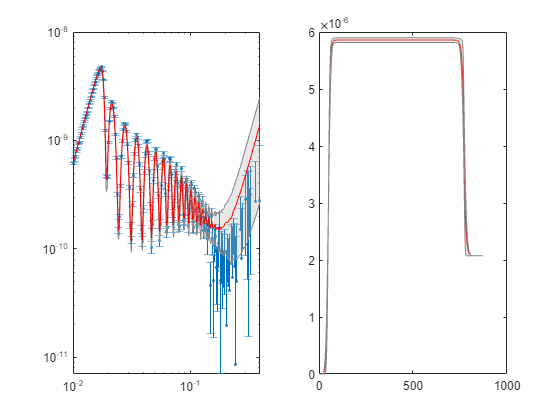


    figure(31); clf;
    bayesShadedPlot(problem,results,'fit','average','KeepAxes',true,'interval',65,'q4',true);


    h4 = figure(6); clf

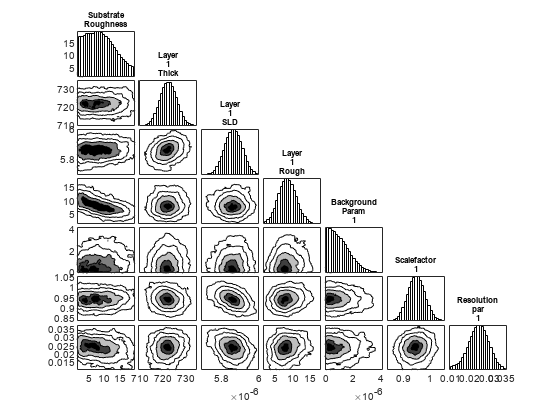

    cornerPlot(results,h4,'smooth',false)

Keep these reults..

resultsPolref = results;

We can also do the same with the CRISP data....

crispData = readtable([fileDir filesep 'CRISP' filesep 'IvsQ_104703_104704_104705.dat']);
crispData = table2array(crispData);
problem.addData('CRISP',crispData);

% set the data to CRISP and re-run...
problem.setContrast(1,'Data','CRISP');

[problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________


Running DREAM

------------------ Summary of the main settings used ------------------


DREAMPar = struct with fields:
             d: 7
             N: 10
             T: 5000
      parallel: 0
           CPU: 1
        lambda: 0.500000000000000
    pUnitGamma: 0.200000000000000
           nCR: 3
         delta: 3
         steps: 100
          zeta: 1.000000000000000e-12
       outlier: 'iqr'
      adaptPCR: 0
      thinning: 1
       epsilon: 0.025000000000000
           ABC: 0
            IO: 0
        modout: 0
       restart: 0
          save: 0
             R: [10×10 double]


-----------------------------------------------------------------------

 DREAM:  100.0% [****************************************]
Elapsed time is 8.243149 seconds.

Finished RAT ______________________________________________________________________________________________ 



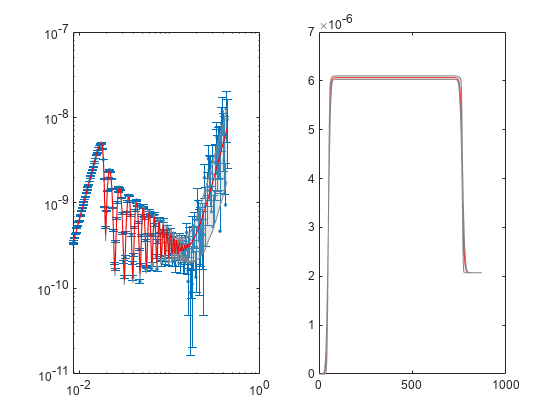


figure(32); clf;
bayesShadedPlot(problem,results,'fit','average','KeepAxes',true,'interval',65,'q4',true);

h4 = figure(7); clf

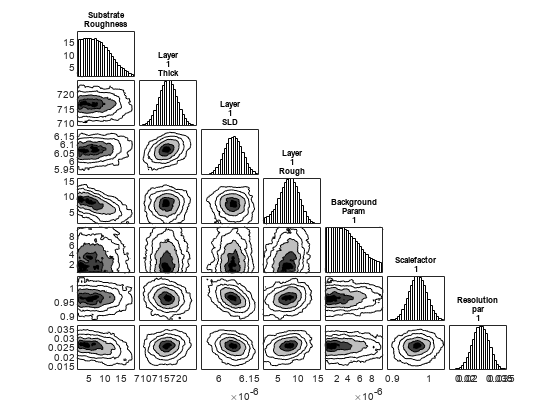

cornerPlot(results,h4,'smooth',false)

% save this data also....
resultsCrisp = results;

## Comparison of Instruments...

Make a common plot of all the histograms...

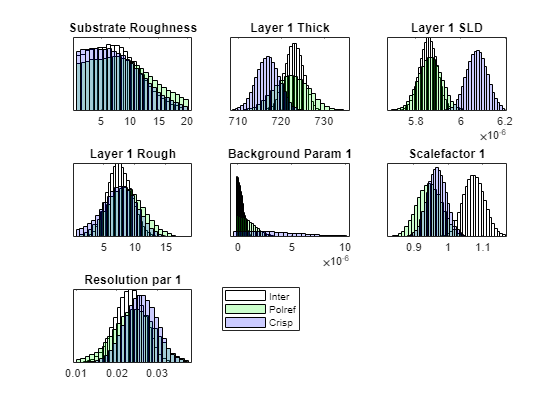

chainInter = resultsInter.chain;
chainPolref = resultsPolref.chain;
chainCrisp = resultsCrisp.chain;
fitNames = resultsInter.fitNames; % same for all...


figure(20); hold on; clf
    [~,npar2]=size(chainInter);
    inds = 1:npar2;

    % Plot the histograms....
    np  = length(inds);
    ns1 = ceil(sqrt(np));
    ns2 = round(sqrt(np));
    for i=1:np
        h=subplot(ns1,ns2,i);

        % Inter....
        thisChain = chainInter(:,inds(i));
    
        [N,edges] = histcounts(thisChain,25, 'Normalization','pdf');
        edges2 = edges(2:end) - (edges(2)-edges(1))/2;
    
        N = smoothdata(N, 'movmean');
    
        bar(edges2,N,1,'w','FaceAlpha',0.2); hold on
    
        set(h,'ytick',[]);
        title(sprintf('%s',fitNames{i}))

        % Polref....
        thisChain = chainPolref(:,inds(i));
    
        [N,edges] = histcounts(thisChain,25, 'Normalization','pdf');
        edges2 = edges(2:end) - (edges(2)-edges(1))/2;
    
        N = smoothdata(N, 'movmean');
    
        bar(edges2,N,1,'g','FaceAlpha',0.2); hold on

        % Crisp....
        thisChain = chainCrisp(:,inds(i));
    
        [N,edges] = histcounts(thisChain,25, 'Normalization','pdf');
        edges2 = edges(2:end) - (edges(2)-edges(1))/2;
    
        N = smoothdata(N, 'movmean');
    
        bar(edges2,N,1,'b','FaceAlpha',0.2); hold on

    end

    legend({'Inter','Polref','Crisp'});
    
subplot(3,3,7)
legend("Position", [0.40845,0.21798,0.11607,0.090476])

## Joint Analysis of all runs....

even though there are slight differences between the results, they are close enough that we can do a joint analysis over all three datasets. To do that, each set will need it's own background, scalefactor and resolution. Re-configure our peoject to do that....


% Add scalefactors...
problem.setScalefactor(1,'name','Inter Scalefac');
problem.addScalefactor('Polref Scalefac',0.8,1,1.2,true);
problem.addScalefactor('Crisp Scalefac',0.8,1,1.2,true);

% And background...
problem.setBackgroundParam(1,'name','Inter');
problem.addBackgroundParam('Polref',-1e-7,3e-6,1e-5,true);
problem.addBackgroundParam('Crisp',-1e-7,3e-6,1e-5,true);
problem.setBackground('Background 1','Name','Inter','Value1','Inter');
problem.addBackground('Polref','constant','Polref');
problem.addBackground('Crisp','constant','Crisp');

% Also resolutions.....
problem.setResolutionParam(1,'name','Inter resolPar');
problem.resolution.setResolution(1,'name','Inter Resol','Value1','Inter resolPar');
problem.addResolutionParam('Polref resolPar',0.01,0.022,0.05,true);
problem.addResolutionParam('Crisp resolPar',0.01,0.022,0.05,true);
problem.addResolution('Polref Resol','constant','Polref resolPar');
problem.addResolution('Crisp Resol','constant','Crisp resolPar');

% reconfigure contrast 1
problem.setContrast(1,'Background','Inter',...
                      'Scalefactor','Inter Scalefac',...
                      'Resolution', 'Inter Resol',...
                      'Data', 'Inter 1');
% Add the other two contrasts...
problem.addContrast('Name',         'Polref',...
                    'Data',         'Polref',...
                    'Background',   'Polref',...
                    'Scalefactor',  'Polref Scalefac',...
                    'BulkIn',       'SLD Air',...
                    'BulkOut',      'Silicon',...
                    'Resolution',   'Polref Resol');
problem.setContrastModel(2,'Layer 1');

problem.addContrast('Name',         'Crisp',...
                    'Data',         'CRISP',...
                    'Background',   'Crisp',...
                    'Scalefactor',  'Crisp Scalefac',...
                    'BulkIn',       'SLD Air',...
                    'BulkOut',      'Silicon',...
                    'Resolution',   'Crisp Resol');
problem.setContrastModel(3,'Layer 1');

disp(problem)

         modelType: 'standard layers'
    experimentName: "RoundRobin Sample1"
          geometry: 'air/substrate'


    Parameters: ---------------------------------------------------------------------------------------------- 

    p            Name              Min            Value              Max      Fit? 
    _    _____________________    _____    ____________________    _______    _____

    1    "Substrate Roughness"        1         7.0740604683671         20    true 
    2    "Layer 1 Thick"             50        716.575357265333       3000    true 
    3    "Layer 1 SLD"            1e-06    6.06640698375411e-06    1.3e-05    true 
    4    "Layer 1 Rough"              1         7.2598568486922         20    true 


    Bulk In: ----------------------------------------------

Now we have a contrast each for each of the datasets.

We make a new controls block, but this time we parallelise over contrasts. This means that each contrast will get it's own dedicated OpenMP thread, which will keep things nice and fast.

controls = controlsClass();
controls.parallel = 'contrasts'

controls =   controlsClass with properties:

            parallel: 'contrasts'
           procedure: 'calculate'
    calcSldDuringFit: 0
             display: 'iter'
           resamPars: [0.900000000000000 50]


Run a quick DE to get the initial result

controls.procedure = 'de';
controls.display = 'final'

controls =   controlsClass with properties:

                parallel: 'contrasts'
               procedure: 'de'
        calcSldDuringFit: 0
                 display: 'final'
          populationSize: 20
                 fWeight: 0.500000000000000
    crossoverProbability: 0.800000000000000
                strategy: 4
             targetValue: 1
          numGenerations: 500
               resamPars: [0.900000000000000 50]


[problem,resultsAll] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________


Running Differential Evolution

Final chi squared is 42.8091
Elapsed time is 1.545371 seconds.

Finished RAT ______________________________________________________________________________________________ 



And plot this out.....

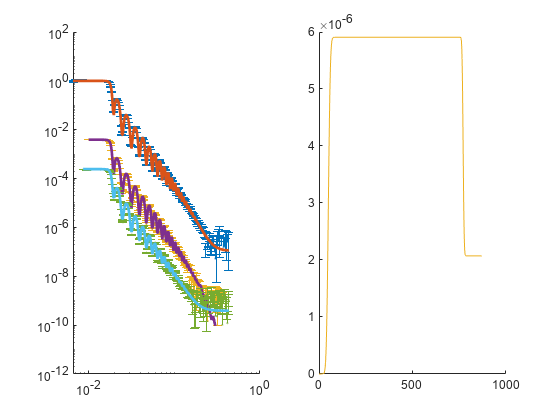

plotRefSLD(problem,resultsAll);

Finally, run a Bayesian analysis over the whole thing.....

controls.procedure = 'dream';
[problem,resultsAll] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________


Running DREAM

------------------ Summary of the main settings used ------------------


DREAMPar = struct with fields:
             d: 13
             N: 10
             T: 5000
      parallel: 0
           CPU: 1
        lambda: 0.500000000000000
    pUnitGamma: 0.200000000000000
           nCR: 3
         delta: 3
         steps: 100
          zeta: 1.000000000000000e-12
       outlier: 'iqr'
      adaptPCR: 0
      thinning: 1
       epsilon: 0.025000000000000
           ABC: 0
            IO: 0
        modout: 0
       restart: 0
          save: 0
             R: [10×10 double]


-----------------------------------------------------------------------

 DREAM:    0.0% [........................................]


 DREAM:  100.0% [****************************************]
Elapsed time is 12.797904 seconds.

Finished RAT ______________________________________________________________________________________________ 



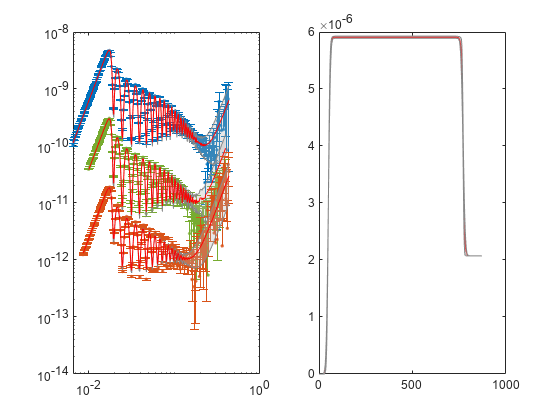


figure;
bayesShadedPlot(problem,resultsAll,'fit','average','interval',65,'q4',true);

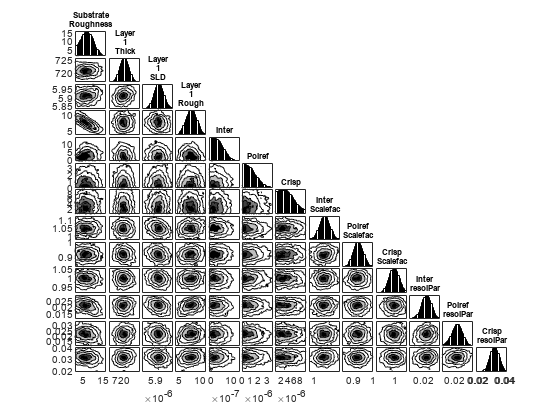

h4 = figure;
cornerPlot(resultsAll,h4,'smooth',false)